# Math 9 Discussion Week 3

## Q: Now we want to examine an interesting class of function:

## $f(x) = \frac{1}{\sqrt{2\pi}\sigma} exp({-\frac{(x-\mu)^2}{2\sigma^2})$ (Normal distribution or Gauss distribution) on [-10, 10]. 

% Define the linespace
% Define the step size
number = 1e3

number = 1000

% Define the upper bound
upper = 100

upper = 100

h = 2*upper/number

h = 0.2000

x = -upper: h : upper

x =  -100.0000  -99.8000  -99.6000  -99.4000  -99.2000  -99.0000  -98.8000  -98.6000  -98.4000  -98.2000  -98.0000  -97.8000  -97.6000  -97.4000  -97.2000  -97.0000  -96.8000  -96.6000  -96.4000  -96.2000  -96.0000  -95.8000  -95.6000  -95.4000  -95.2000  -95.0000  -94.8000  -94.6000  -94.4000  -94.2000  -94.0000  -93.8000  -93.6000  -93.4000  -93.2000  -93.0000  -92.8000  -92.6000  -92.4000  -92.2000  -92.0000  -91.8000  -91.6000  -91.4000  -91.2000  -91.0000  -90.8000  -90.6000  -90.4000  -90.2000




% Define the function
mu = 2

mu = 2

sigma = 8

sigma = 8

f = @(x) 1/(sqrt(2*pi)*sigma)*exp(-(x-mu).^2./(2*sigma^2))

f = function_handle with value:
    @(x)1/(sqrt(2*pi)*sigma)*exp(-(x-mu).^2./(2*sigma^2))


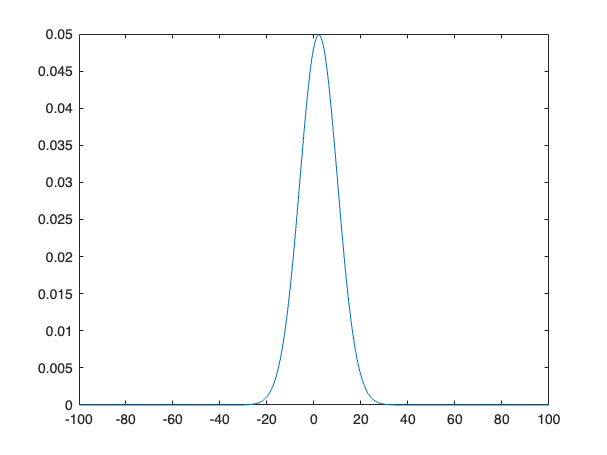

plot(x, f(x))


% Define the derivative
delta = 0.0095

delta = 0.0095

derf = @(x) (f(x+delta) - f(x))./delta

derf = function_handle with value:
    @(x)(f(x+delta)-f(x))./delta


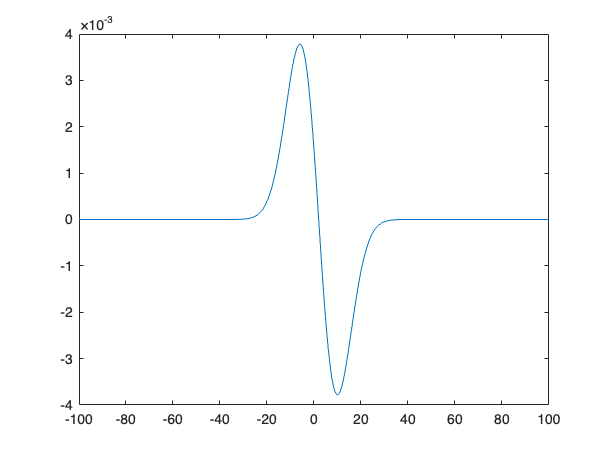

plot(x, derf(x))


% Define the integration
antiderf = @(x) h.*cumsum(f(x))

antiderf = function_handle with value:
    @(x)h.*cumsum(f(x))


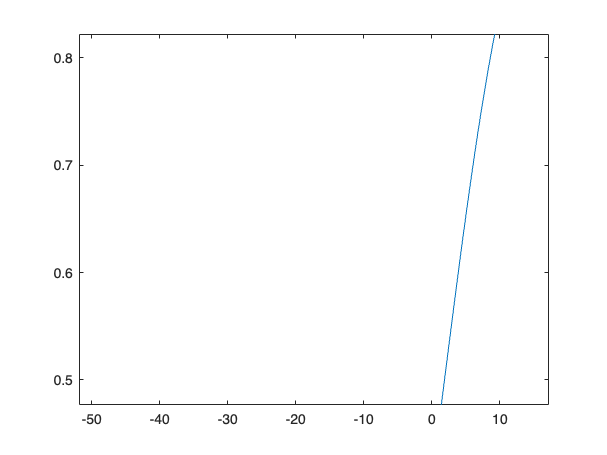

plot(x, antiderf(x))

## Can we do better when we define the derivative and the antiderivative of the Gauss distribution? See what if I want to examine the derivative and the antiderivative of other functions?

% We need to define some reusable functions
function d = der(f, delta)
    d = @(x) (f(x+delta) - f(x))./delta;
end

function int = int(f, h)
    int = @(x) h.*cumsum(f(x))
end

% Or use a seperate file to store our function. 
% Note in matlab, we can only store one function in one .m file
edit Math9Dis3_function.m

k = Math9Dis3_function(f,delta)

k = function_handle with value:
    @(x)(f(x+delta)-f(x))./delta


plot(x, k(x))